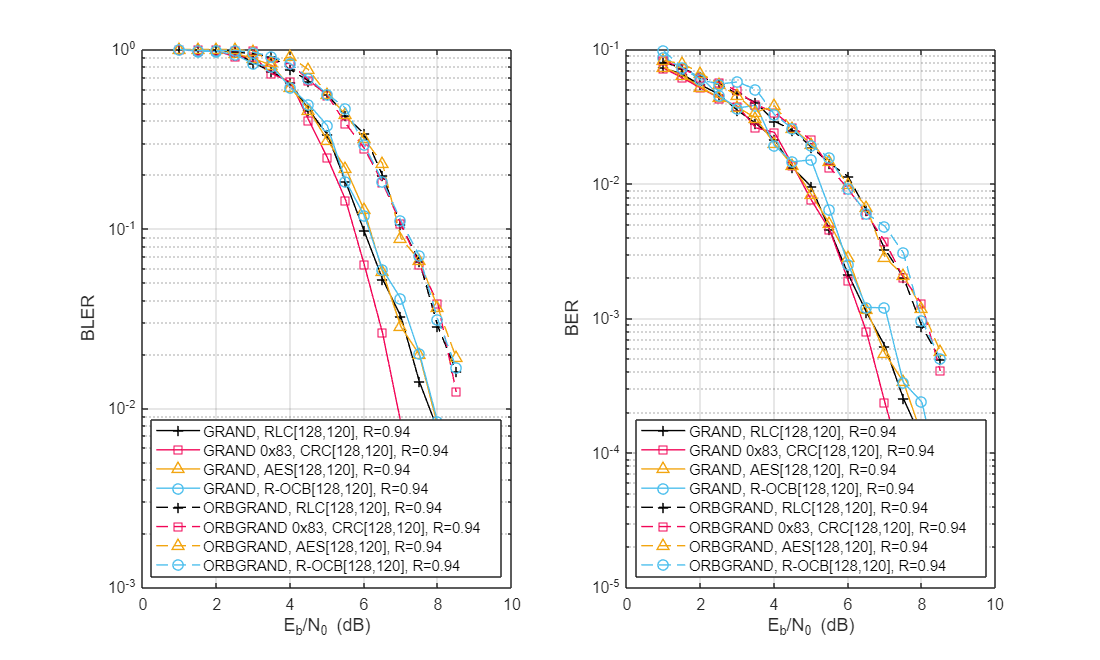

% Add RESULTE folder to path
% addpath('ROCB_GIT/RESULTS/');
addpath('RESULTS/');
addpath('Figures/');

% Load all .mat files 128_120
data1_120 = load('RESULTS/BSC_GRAND_RLC_128_120_1.mat');
data2_120 = load('RESULTS/BSC_GRAND_CRC_0x83_128_120_1.mat');
data3_120 = load('RESULTS/BSC_GRAND_AESwitFEC_128_120_1.mat');
data4_120 = load('RESULTS/BSC_GRAND_ROCB_128_120_1.mat');
data5_120 = load('RESULTS/BSC_ORBGRAND_RLC_128_120_1.mat');
data6_120 = load('RESULTS/BSC_ORBGRAND_CRC_0x83_128_120_1.mat');
data7_120 = load('RESULTS/BSC_ORBGRAND_AESwitFEC_128_120_1.mat');
data8_120 = load('RESULTS/BSC_ORBGRAND_ROCB_128_120_1.mat');

% Load all .mat files 128_116
data1_116 = load('RESULTS/BSC_GRAND_CAPOLAR_128_116_1.mat');
data2_116 = load('RESULTS/BSC_GRAND_RLC_128_116_1.mat');
data3_116 = load('RESULTS/BSC_GRAND_CRC_0x8f3_128_116_1.mat');
data4_116 = load('RESULTS/BSC_GRAND_AESwitFEC_128_116_1.mat');
data5_116 = load('RESULTS/BSC_GRAND_ROCB_128_116_1.mat');
data6_116 = load('RESULTS/BSC_GRAND_ROCB_CRC_128_116_1.mat');
data7_116 = load('RESULTS/BSC_ORBGRAND_CAPOLAR_128_116_1.mat');
data8_116 = load('RESULTS/BSC_ORBGRAND_RLC_128_116_1.mat');
data9_116 = load('RESULTS/BSC_ORBGRAND_CRC_0x8f3_128_116_1.mat');
data10_116 = load('RESULTS/BSC_ORBGRAND_AESwitFEC_128_116_1.mat');
data11_116 = load('RESULTS/BSC_ORBGRAND_ROCB_128_116_1.mat');
data12_116 = load('RESULTS/BSC_ORBGRAND_ROCB_CRC_128_116_1.mat');

% Load all .mat files 128_112
data1_112 = load('RESULTS/BSC_GRAND_CAPOLAR_128_112_1.mat');
data2_112 = load('RESULTS/BSC_GRAND_RLC_128_112_1.mat');
data3_112 = load('RESULTS/BSC_GRAND_CRC_0x9eb2_128_112_1.mat');
data4_112 = load('RESULTS/BSC_GRAND_AESwitFEC_128_112_1.mat');
data5_112 = load('RESULTS/BSC_GRAND_ROCB_128_112_1.mat');
data6_112 = load('RESULTS/BSC_ORBGRAND_CAPOLAR_128_112_1.mat');
data7_112 = load('RESULTS/BSC_ORBGRAND_RLC_128_112_1.mat');
data8_112 = load('RESULTS/BSC_ORBGRAND_CRC_0x9eb2_128_112_1.mat');
data9_112 = load('RESULTS/BSC_ORBGRAND_AESwitFEC_128_112_1.mat');
data10_112 = load('RESULTS/BSC_ORBGRAND_ROCB_128_112_1.mat');

% Extract code structs
codes_120 = {data1_120.code, data2_120.code, data3_120.code, data4_120.code, data5_120.code, ...
         data6_120.code, data7_120.code, data8_120.code};



codes_116 = {data1_116.code, data2_116.code, data3_116.code, data4_116.code, data5_116.code, ...
         data6_116.code, data7_116.code, data8_116.code, data9_116.code, ...
         data10_116.code, data11_116.code, data12_116.code};

codes_112 = {data1_112.code, data2_112.code, data3_112.code, data4_112.code, data5_112.code, ...
         data6_112.code, data7_112.code, data8_112.code, data9_112.code, data10_112.code};


% Define labels and markers
labels_120 = {'GRAND, RLC[128,120], R=0.94', 'GRAND 0x83, CRC[128,120], R=0.94', ...
          'GRAND, AES[128,120], R=0.94', 'GRAND, R-OCB[128,120], R=0.94', ...
          'ORBGRAND, RLC[128,120], R=0.94', 'ORBGRAND 0x83, CRC[128,120], R=0.94', 'ORBGRAND, AES[128,120], R=0.94', ...
          'ORBGRAND, R-OCB[128,120], R=0.94'};


labels_116 = {'GRAND, CAPOLAR[128,116], R=0.91', 'GRAND, RLC[128,116], R=0.91', ... 
          'GRAND 0x8f3, CRC[128,116], R=0.91', 'GRAND, AES[128,116], R=0.91', ...
          'GRAND, R-OCB[128,116], R=0.91', 'GRAND, R-OCB with CRC[128,116], R=0.91', ...
          'ORBGRAND, CAPOLAR[128,116], R=0.91', 'ORBGRAND, RLC[128,116], R=0.91', ... 
          'ORBGRAND 0x8f3, CRC[128,116], R=0.91', 'ORBGRAND, AES[128,116], R=0.91', ...
          'ORBGRAND, R-OCB[128,116], R=0.91', 'ORBGRAND, R-OCB with CRC[128,116], R=0.91'};

labels_112 = {'GRAND, CAPOLAR[128,112], R=0.88', 'GRAND, RLC[128,112], R=0.88', 'GRAND 0x9eb2, CRC[128,112], R=0.88', ...
          'GRAND, AES[128,112], R=0.88', 'GRAND, R-OCB[128,112], R=0.88', 'ORBGRAND, CAPOLAR[128,112], R=0.88', ...
          'ORBGRAND, RLC[128,112], R=0.88', 'ORBGRAND 0x9eb2, CRC[128,112], R=0.88', 'ORBGRAND, AES[128,112], R=0.88', ...
          'ORBGRAND, R-OCB[128,112], R=0.88'};

markers = {'-*', '-+', '-s', '-^', '-o', '--*', '--+', '--s', '--^', '--o'};
markers_116 = {'-*', '-+', '-s', '-^', '-o', '-X', '--*', '--+', '--s', '--^', '--o', '--X'};
markers_120 = { '-+', '-s', '-^', '-o', '--+', '--s', '--^', '--o'};

% Define colors (distinguish GRAND vs ORBGRAND and BSC vs AWGN)
colors_116 = {[0.1098, 0.5804, 0.2510],      % Green - GRAND CAPOLAR
          [0, 0, 0],                     % Black - GRAND RLC  
          [0.9490, 0.0235, 0.3412],      % Red - GRAND CRC
          [0.9490, 0.6471, 0.0627],      % Yellow - GRAND AES
          [0.30 0.75 0.93],              % Blue - GRAND R-OCB
          [0.1 0.9 0.5],                 % XXX - GRAND R-OCB CRC
          [0.1098, 0.5804, 0.2510],      % Green - ORBGRAND CAPOLAR
          [0, 0, 0],                     % Black - ORBGRAND RLC  
          [0.9490, 0.0235, 0.3412],      % Red - ORBGRAND CRC
          [0.9490, 0.6471, 0.0627],     % Yellow - ORBGRAND AES
          [0.30 0.75 0.93],              % Blue - ORBGRAND R-OCB
          [0.1 0.9 0.5]};            % XXX - ORBGRAND R-OCB CRC

colors_tmp_120 = {
          [0, 0, 0],                     % Black - GRAND RLC  
          [0.9490, 0.0235, 0.3412],      % Red - GRAND CRC
          [0.9490, 0.6471, 0.0627],      % Yellow - GRAND AES
          [0.30 0.75 0.93],              % Blue - GRAND R-OCB
          [0, 0, 0],                     % Black - ORBGRAND RLC  
          [0.9490, 0.0235, 0.3412],      % Red - ORBGRAND CRC
          [0.9490, 0.6471, 0.0627],     % Yellow - ORBGRAND AES
          [0.30 0.75 0.93]};            % Blue - ORBGRAND R-OCB

colors_tmp_112 = {[0.1098, 0.5804, 0.2510],      % Green - GRAND CAPOLAR
          [0, 0, 0],                     % Black - GRAND RLC  
          [0.9490, 0.0235, 0.3412],      % Red - GRAND CRC
          [0.9490, 0.6471, 0.0627],      % Yellow - GRAND AES
          [0.30 0.75 0.93],              % Blue - GRAND R-OCB
          [0.1098, 0.5804, 0.2510],      % Green - ORBGRAND CAPOLAR
          [0, 0, 0],                     % Black - ORBGRAND RLC  
          [0.9490, 0.0235, 0.3412],      % Red - ORBGRAND CRC
          [0.9490, 0.6471, 0.0627],     % Yellow - ORBGRAND AES
          [0.30 0.75 0.93]};            % Blue - ORBGRAND R-OCB

         

% Filter out empty or problematic data
valid_indices_120 = [];
for i = 1:length(codes_120)
    if ~isempty(codes_120{i}) && isfield(codes_120{i}, 'ebn0') && isfield(codes_120{i}, 'BLER') && isfield(codes_120{i}, 'BER')
        if length(codes_120{i}.ebn0) > 0 && length(codes_120{i}.BLER) > 0
            valid_indices_120 = [valid_indices_120, i];
        end
    end
end

valid_indices_116 = [];
for i = 1:length(codes_116)
    if ~isempty(codes_116{i}) && isfield(codes_116{i}, 'ebn0') && isfield(codes_116{i}, 'BLER') && isfield(codes_116{i}, 'BER')
        if length(codes_116{i}.ebn0) > 0 && length(codes_116{i}.BLER) > 0
            valid_indices_116 = [valid_indices_116, i];
        end
    end
end

valid_indices_112 = [];
for i = 1:length(codes_112)
    if ~isempty(codes_112{i}) && isfield(codes_112{i}, 'ebn0') && isfield(codes_112{i}, 'BLER') && isfield(codes_112{i}, 'BER')
        if length(codes_112{i}.ebn0) > 0 && length(codes_112{i}.BLER) > 0
            valid_indices_112 = [valid_indices_112, i];
        end
    end
end

% Plot BLER k=120
figure('Position', [100, 100, 1000, 600]);
subplot(1, 2, 1);
for i = valid_indices_120
    code = codes_120{i};
    % Handle data length consistency
    min_len = min(length(code.ebn0), length(code.BLER));
    ebn0_plot = code.ebn0(1:min_len);
    bler_plot = code.BLER(1:min_len);
    
    % Limit CRC GRAND curve for k=120 to Eb/N0 <= 8 dB
    if i == 2
        keep = ebn0_plot <= 7.5;
        ebn0_plot = ebn0_plot(keep);
        bler_plot = bler_plot(keep);
    end

    if i >4 
        keep = ebn0_plot <= 8.5;
        ebn0_plot = ebn0_plot(keep);
        bler_plot = bler_plot(keep);
    end

    % Remove zero or negative BLER values for log plot
    valid_points = bler_plot > 0;
    if sum(valid_points) > 0
        semilogy(ebn0_plot(valid_points), bler_plot(valid_points), markers_120{i}, ...
                'DisplayName', labels_120{i}, 'Color', colors_tmp_120{i}, 'LineWidth', 0.95, 'MarkerSize', 7);
        hold on;
    end
end
grid on;
xlabel('E_b/N_0 (dB)', 'FontSize', 12);
ylabel('BLER', 'FontSize', 12);
legend('Location', 'best', 'FontSize', 10);
% title('Block Error Rate vs E_b/N_0', 'FontSize', 14);
set(gca, 'FontSize', 11);

% Plot BER k=120
subplot(1, 2, 2);
for i = valid_indices_120
    code = codes_120{i};
    % Handle data length consistency
    min_len = min(length(code.ebn0), length(code.BER));
    ebn0_plot = code.ebn0(1:min_len);
    ber_plot = code.BER(1:min_len);

    % Limit CRC GRAND curve for k=120 to Eb/N0 <= 7.5 dB
    if i == 2
        keep = ebn0_plot <= 7.5;
        ebn0_plot = ebn0_plot(keep);
        ber_plot = ber_plot(keep);
    end

    if i >4
        keep = ebn0_plot <= 8.5;
        ebn0_plot = ebn0_plot(keep);
        ber_plot = ber_plot(keep);
    end
    
    % Remove zero or negative BER values for log plot
    valid_points = ber_plot > 0;
    if sum(valid_points) > 0
        semilogy(ebn0_plot(valid_points), ber_plot(valid_points), markers_120{i}, ...
                'DisplayName', labels_120{i}, 'Color', colors_tmp_120{i}, 'LineWidth', 0.95, 'MarkerSize', 7);
        hold on;
    end
end
grid on;
xlabel('E_b/N_0 (dB)', 'FontSize', 12);
ylabel('BER', 'FontSize', 12);
legend('Location', 'best', 'FontSize', 10);
% title('Bit Error Rate vs E_b/N_0', 'FontSize', 14);
set(gca, 'FontSize', 11);

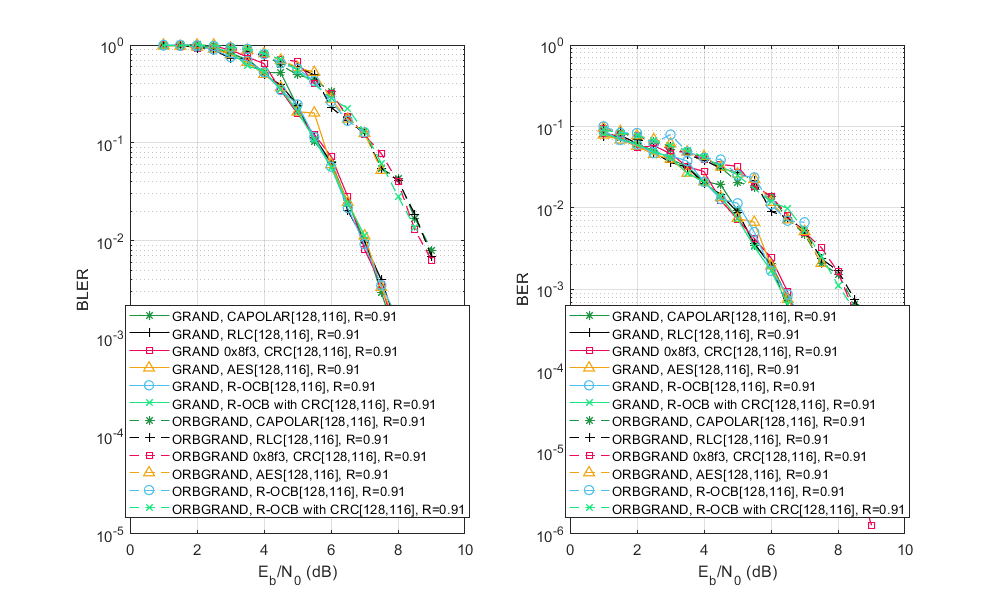


% Plot BLER k=116
figure('Position', [100, 100, 1000, 600]);
subplot(1, 2, 1);
for i = valid_indices_116
    code = codes_116{i};
    % Handle data length consistency
    min_len = min(length(code.ebn0), length(code.BLER));
    ebn0_plot = code.ebn0(1:min_len);
    bler_plot = code.BLER(1:min_len);
    
    % Remove zero or negative BLER values for log plot
    valid_points = bler_plot > 0;
    if sum(valid_points) > 0
        semilogy(ebn0_plot(valid_points), bler_plot(valid_points), markers_116{i}, ...
                'DisplayName', labels_116{i}, 'Color', colors_116{i}, 'LineWidth', 0.95, 'MarkerSize', 7);
        hold on;
    end
end
grid on;
xlabel('E_b/N_0 (dB)', 'FontSize', 12);
ylabel('BLER', 'FontSize', 12);
legend('Location', 'best', 'FontSize', 10);
% title('Block Error Rate vs E_b/N_0', 'FontSize', 14);
set(gca, 'FontSize', 11);

% Plot BER k=116
subplot(1, 2, 2);
for i = valid_indices_116
    code = codes_116{i};
    % Handle data length consistency
    min_len = min(length(code.ebn0), length(code.BER));
    ebn0_plot = code.ebn0(1:min_len);
    ber_plot = code.BER(1:min_len);
    
    % Remove zero or negative BER values for log plot
    valid_points = ber_plot > 0;
    if sum(valid_points) > 0
        semilogy(ebn0_plot(valid_points), ber_plot(valid_points), markers_116{i}, ...
                'DisplayName', labels_116{i}, 'Color', colors_116{i}, 'LineWidth', 0.95, 'MarkerSize', 7);
        hold on;
    end
end
grid on;
xlabel('E_b/N_0 (dB)', 'FontSize', 12);
ylabel('BER', 'FontSize', 12);
legend('Location', 'best', 'FontSize', 10);
% title('Bit Error Rate vs E_b/N_0', 'FontSize', 14);
set(gca, 'FontSize', 11);

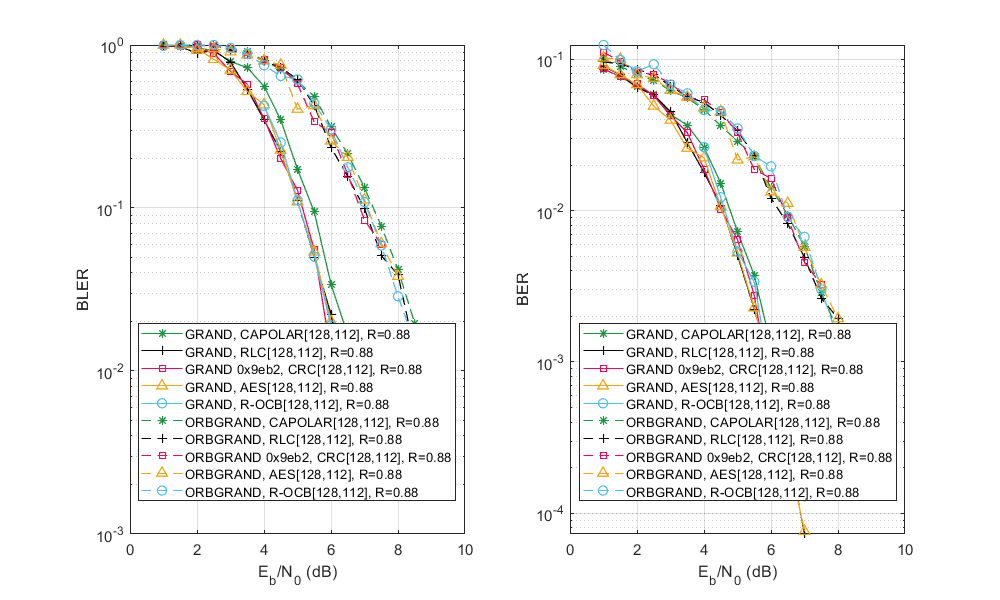






% Plot BLER k=112
figure('Position', [100, 100, 1000, 600]);
subplot(1, 2, 1);
for i = valid_indices_112
    code = codes_112{i};
    % Handle data length consistency
    min_len = min(length(code.ebn0), length(code.BLER));
    ebn0_plot = code.ebn0(1:min_len);
    bler_plot = code.BLER(1:min_len);

    if i <= 5
        keep = ebn0_plot <= 7;
        ebn0_plot = ebn0_plot(keep);
        bler_plot = bler_plot(keep);
    end
    
    % Remove zero or negative BLER values for log plot
    valid_points = bler_plot > 0;
    if sum(valid_points) > 0
        semilogy(ebn0_plot(valid_points), bler_plot(valid_points), markers{i}, ...
                'DisplayName', labels_112{i}, 'Color', colors_tmp_112{i}, 'LineWidth', 0.95, 'MarkerSize', 7);
        hold on;
    end
end
grid on;
xlabel('E_b/N_0 (dB)', 'FontSize', 12);
ylabel('BLER', 'FontSize', 12);
legend('Location', 'best', 'FontSize', 10);
% title('Block Error Rate vs E_b/N_0', 'FontSize', 14);
set(gca, 'FontSize', 11);

% Plot BER k=112
subplot(1, 2, 2);
for i = valid_indices_112
    code = codes_112{i};
    % Handle data length consistency
    min_len = min(length(code.ebn0), length(code.BER));
    ebn0_plot = code.ebn0(1:min_len);
    ber_plot = code.BER(1:min_len);

    if i <= 5
        keep = ebn0_plot <= 7;
        ebn0_plot = ebn0_plot(keep);
        ber_plot = ber_plot(keep);
    end
    
    % Remove zero or negative BER values for log plot
    valid_points = ber_plot > 0;
    if sum(valid_points) > 0
        semilogy(ebn0_plot(valid_points), ber_plot(valid_points), markers{i}, ...
                'DisplayName', labels_112{i}, 'Color', colors_tmp_112{i}, 'LineWidth', 0.95, 'MarkerSize', 7);
        hold on;
    end
end
grid on;
xlabel('E_b/N_0 (dB)', 'FontSize', 12);
ylabel('BER', 'FontSize', 12);
legend('Location', 'best', 'FontSize', 10);
% title('Bit Error Rate vs E_b/N_0', 'FontSize', 14);
set(gca, 'FontSize', 11);




% % Adjust subplot spacing
% % sgtitle('GRAND and ORBGRAND Performance Comparison (BSC)', 'FontSize', 16);
% 
% % Optional: Create separate plots for GRAND vs ORBGRAND
% figure('Position', [200, 200, 1000, 400]);
% 
% % GRAND algorithms only
% subplot(1, 2, 1);
% grand_indices = [1, 2, 3, 4, 5]; % GRAND algorithms
% for i = intersect(grand_indices, valid_indices)
%     code = codes{i};
%     min_len = min(length(code.ebn0), length(code.BLER));
%     ebn0_plot = code.ebn0(1:min_len);
%     bler_plot = code.BLER(1:min_len);
%     valid_points = bler_plot > 0;
%     if sum(valid_points) > 0
%         semilogy(ebn0_plot(valid_points), bler_plot(valid_points), markers{i}, ...
%                 'DisplayName', labels{i}, 'Color', colors{i}, 'LineWidth', 1.5, 'MarkerSize', 6);
%         hold on;
%     end
% end
% grid on;
% xlabel('E_b/N_0 (dB)', 'FontSize', 12);
% ylabel('BLER', 'FontSize', 12);
% legend('Location', 'best', 'FontSize', 10);
% title('GRAND Algorithms', 'FontSize', 14);
% 
% % ORBGRAND algorithms only
% subplot(1, 2, 2);
% orbgrand_indices = [6, 7, 8, 9, 10]; % ORBGRAND algorithms
% for i = intersect(orbgrand_indices, valid_indices)
%     code = codes{i};
%     min_len = min(length(code.ebn0), length(code.BLER));
%     ebn0_plot = code.ebn0(1:min_len);
%     bler_plot = code.BLER(1:min_len);
%     valid_points = bler_plot > 0;
%     if sum(valid_points) > 0
%         semilogy(ebn0_plot(valid_points), bler_plot(valid_points), markers{i}, ...
%                 'DisplayName', labels{i}, 'Color', colors{i}, 'LineWidth', 1.5, 'MarkerSize', 6);
%         hold on;
%     end
% end
% grid on;
% xlabel('E_b/N_0 (dB)', 'FontSize', 12);
% ylabel('BLER', 'FontSize', 12);
% legend('Location', 'best', 'FontSize', 10);
% title('ORBGRAND Algorithms', 'FontSize', 14);
% 
% sgtitle('GRAND vs ORBGRAND Performance', 'FontSize', 16);
% 
% % Print summary information
% fprintf('\nData Summary:\n');
% fprintf('%-25s %-10s %-15s %-15s\n', 'Algorithm', 'Points', 'Eb/N0 Range', 'Min BLER');
% fprintf('%s\n', repmat('-', 1, 70));
% for i = valid_indices
%     code = codes{i};
%     min_len = min(length(code.ebn0), length(code.BLER));
%     valid_bler = code.BLER(1:min_len);
%     valid_bler = valid_bler(valid_bler > 0);
%     if ~isempty(valid_bler)
%         fprintf('%-25s %-10d [%.1f, %.1f]     %.2e\n', ...
%                 labels{i}, min_len, ...
%                 min(code.ebn0(1:min_len)), max(code.ebn0(1:min_len)), ...
%                 min(valid_bler));
%     end
% end
